clc, clear
%Bu proje kesikli reaktörlerle alakalı hesaplamalar yapar
disp('===================SABİT HACİMLİ KESİKLİ REAKTÖRLER(BR)===================')

===================SABİT HACİMLİ KESİKLİ REAKTÖRLER(BR)===================



n = input('Reaksiyon derecesini giriniz: ')

n = 10

k = input('Reaksiyon Sabitini Giriniz: ')

k = 10

CA0 = input('Bileşenin Başlangıç Derişimini Giriniz: ')

CA0 = 10

tmax = input('Süreyi giriniz: ')

tmax = 20

tspan = [0 , tmax]

tspan =      0    20




%Diferansiyel Denklemin Tanımlaması
ode_fun = @(t,CA) -k*CA^n

ode_fun = function_handle with value:
    @(t,CA)-k*CA^n



[t,CA] = ode45(ode_fun , tspan ,CA0)

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


CA =    10.0000
    9.5704
    9.2948
    9.1380
    9.0013
    8.8585
    8.7356
    8.6280
    8.5323
    8.3184
    8.1497
    8.0124
    7.8947
    7.7315
    7.5972


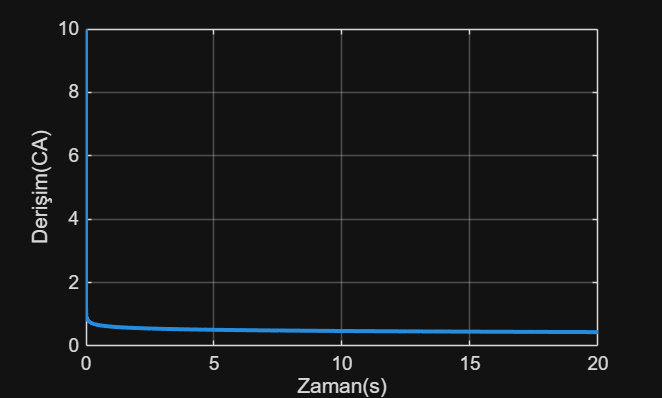


figure;
plot(t, CA, 'LineWidth', 2)
xlabel('Zaman(s)')
ylabel('Derişim(CA)')
grid on;